% 训练 SVM 分类器

## 加载 Fisher 鸢尾花数据集。

删除萼片的长度和宽度以及所有观测到的山鸢尾花。

load fisheriris
inds = ~strcmp(species,'setosa');
X = meas(inds,3:4);
y = species(inds);

## 使用经过处理的数据集训练 SVM 分类器。

SVMModel = fitcsvm(X,y)

SVMModel =   ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'versicolor'  'virginica'}
           ScoreTransform: 'none'
          NumObservations: 100
                    Alpha: [24×1 double]
                     Bias: -14.4149
         KernelParameters: [1×1 struct]
           BoxConstraints: [100×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [100×1 logical]
                   Solver: 'SMO'


  Properties, Methods


% SVMModel = 
%   ClassificationSVM
%              ResponseName: 'Y'
%     CategoricalPredictors: []
%                ClassNames: {'versicolor'  'virginica'}
%            ScoreTransform: 'none'
%           NumObservations: 100
%                     Alpha: [24x1 double]
%                      Bias: -14.4149
%          KernelParameters: [1x1 struct]
%            BoxConstraints: [100x1 double]
%           ConvergenceInfo: [1x1 struct]
%           IsSupportVector: [100x1 logical]
%                    Solver: 'SMO'


% SVMModel 是经过训练的 ClassificationSVM 分类器。
% 您可以查看 SVMModel 的属性。例如，使用圆点表示法查看类顺序。

classOrder = SVMModel.ClassNames

classOrder = 2×1 cell array
    {'versicolor'}
    {'virginica' }


% classOrder = 2x1 cell
%     {'versicolor'}
%     {'virginica' }

% 第一个类 ('versicolor') 是负类，
% 第二个类 ('virginica') 是正类。
% 您可以使用 'ClassNames' 名称-值对组参数在训练期间更改类顺序。

## 绘制数据的散点图并圈出支持向量。

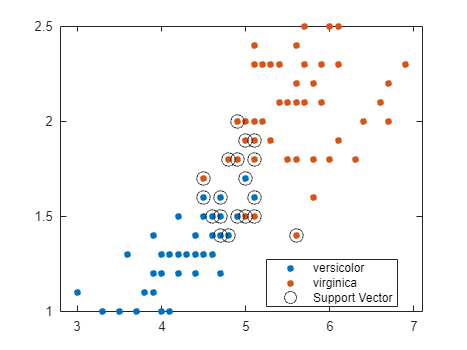

sv = SVMModel.SupportVectors; % 提取支持向量的坐标
figure
gscatter(X(:,1),X(:,2),y)  % 用所有点画图
hold on
plot(sv(:,1),sv(:,2),'ko','MarkerSize',10) % 画支持向量
legend('versicolor','virginica','Support Vector')
hold off


% 支持向量是发生在其估计的类边界之上或之外的观测值。

% 您可以使用 'BoxConstraint' 名称-值对组参数在训练过程中设置框约束来调整边界
% （从而调整支持向量的数量）。